These scripts are for being able to quickly analyze the data from fluorescence traces with different settings. Specifically, this script was for analyzing data from dat/nick_eve2_mhmm folder.

Takes all the traces that meet the condtions in the IF statement. (Some preprocessing might also be done when taking traces from trace_struct_final)


temp = trace_struct_final([trace_struct_final.APbin] == 0);

Reference to non-existent field 'APbin'.


i = 1;
traces = {};
for st = temp
    if length(st.fluo_interp) > 50 && length(st.fluo_interp) < 55
        traces{i} = st.fluo_interp;
        i = i + 1;
    end
end

Uses k means to cluster the data. Extracting data for analysis is done in the following snippet.

%use k means to divide data

num_traces = 0;
for st = trace_struct_final
    if length(st.fluo_interp) > 50 && st.APbin == 0
        num_traces = num_traces + 1;
        new_struct(num_traces) = st;
    end
end

delay = 15;
data = zeros(num_traces,delay-2);
j = 1;
for st = new_struct

    trace = {};
    trace{1} = st.fluo_interp(10:end);
    dat = auto_corr_m_calc_norm(trace,delay);
    dat = dat(2:end) - dat(1:end-1);
    dat = dat(2:end) - dat(1:end-1);
    data(j,:) = dat;
    j = j + 1;

end

idx= kmeans(data,2);

traces = {};
i = 1;
cluster = 2;
for k = 1:length(new_struct)
    if idx(k) == cluster
        traces{i} = new_struct(k).fluo_interp;
        i = i + 1;
    end
end

Script for running cross correlation on all pairs of traces that meet certain requirements. (Should run from src/utilities/ or make sure it's in path)

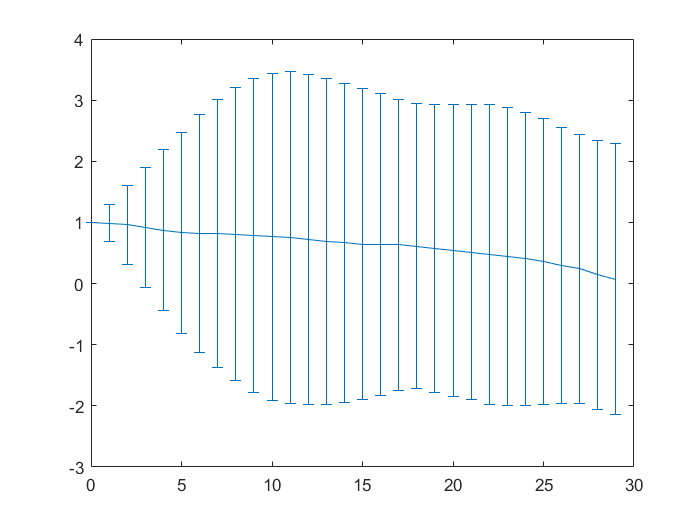


% picks out traces
temp = trace_struct_final([trace_struct_final.APbin] == 0);
i = 1;
traces = {};
for st = temp
    if length(st.fluo_interp) > 100
        traces{i} = st.fluo_interp;
        i = i + 1;
    end
end

%prepares traces for running cross correlation
num_traces = length(traces);
traces1 = cell(1,num_traces * (num_traces - 1));
traces2 = cell(1,num_traces * (num_traces - 1));
i = 1;
for j = 1:num_traces
    for k = 1:num_traces
        if j ~= k
            traces1{i} = traces{j};
            traces2{i} = traces{k};
            i = i + 1;
        end
    end
end
max_delay = 30;
cross_cor = cross_corr_m_calc(traces1,traces2, max_delay);
[std1,std2,std3] = corr_bootstraps(traces1, traces2, max_delay, 30, 'm');
figure()
errorbar(0:max_delay-1, cross_cor, std1);

Splits traces into 12 points fragments and runs autocorrelation on them (4 point overlap in each trace). Generates auto correlation

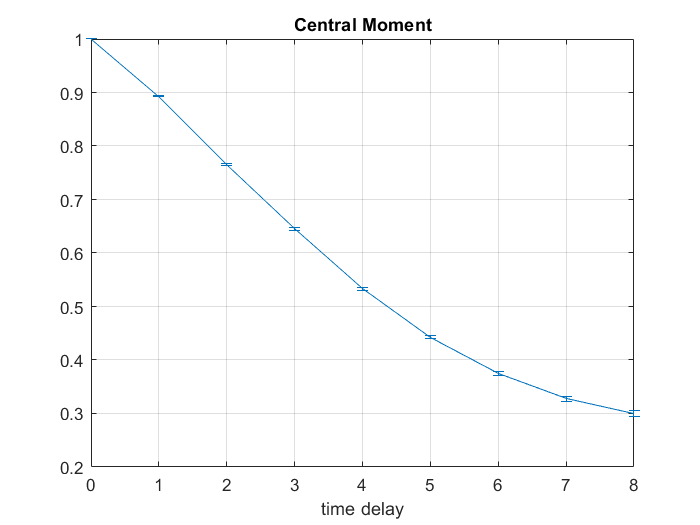

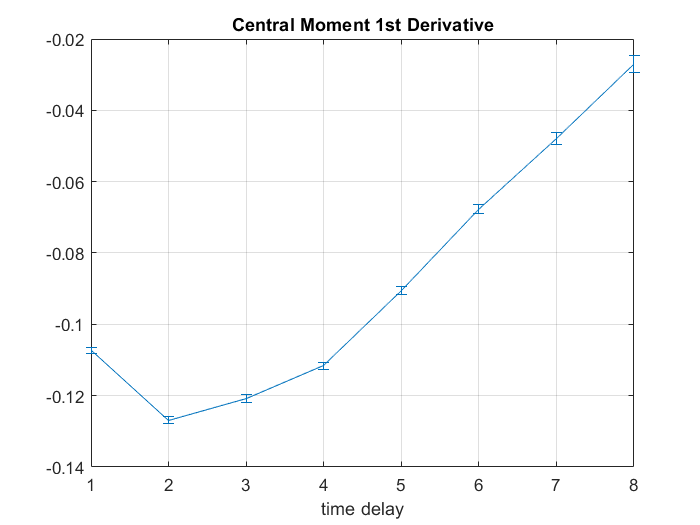

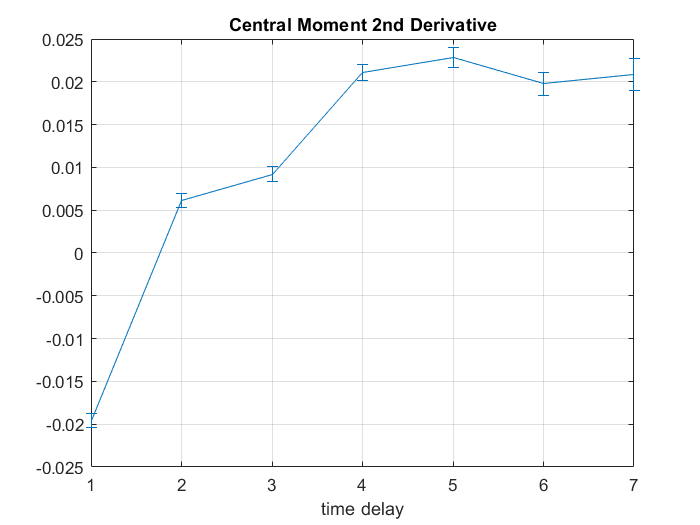

traces = cell(1);
trace_len = 10;
jump = 4;
idx = 1;
for i = 1:length(trace_struct_final)
    fluo = trace_struct_final(i).fluo_interp;
    j = 1;
    while j + trace_len - 1 <= length(fluo)
        traces{idx} = fluo(j:j+trace_len-1);
        idx = idx + 1;
        j = j + jump;
    end
end

gen_auto_cor(traces, 0:2,true,9,0);

Downsamples traces

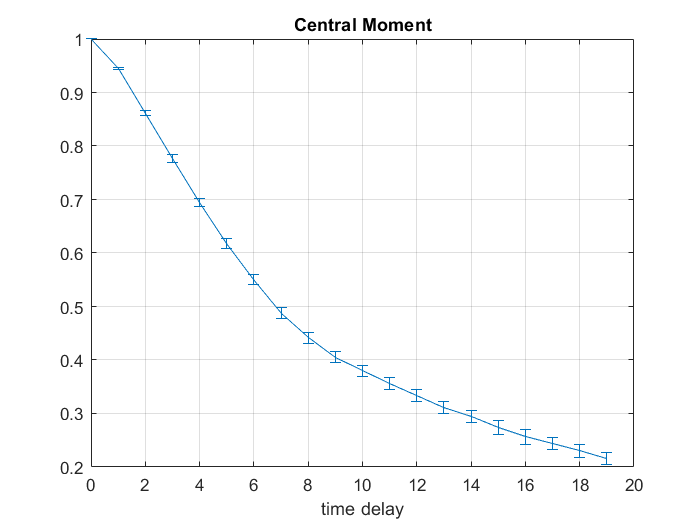

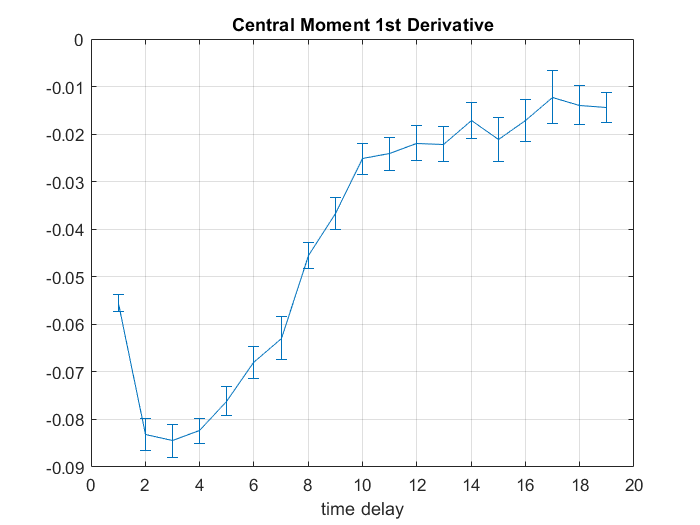

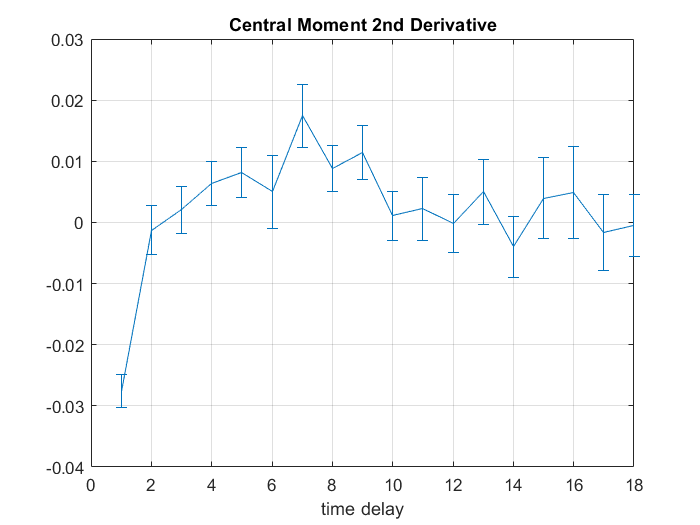

traces = cell(1);
skip = 0;
idx = 1;
for i = 1:length(trace_struct_final)
    fluo = trace_struct_final(i).fluo_interp;
    for s = 1:skip + 1
        traces{idx} = fluo(s:skip+1:end);
        idx = idx + 1;
    end
end

gen_auto_cor(traces,0:2,true,20,0);

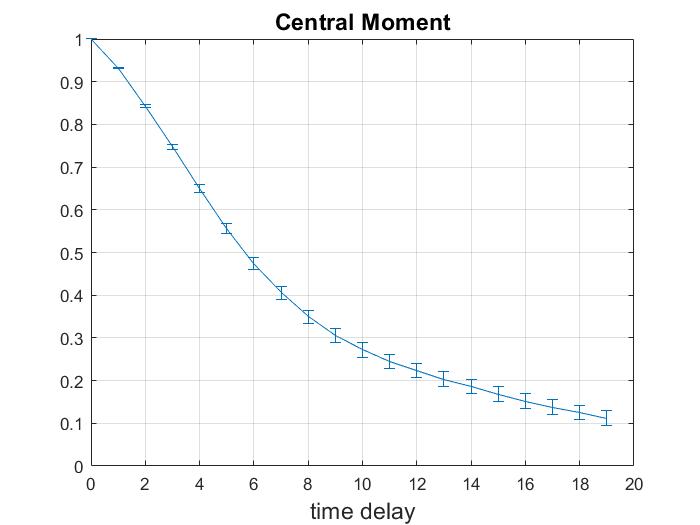

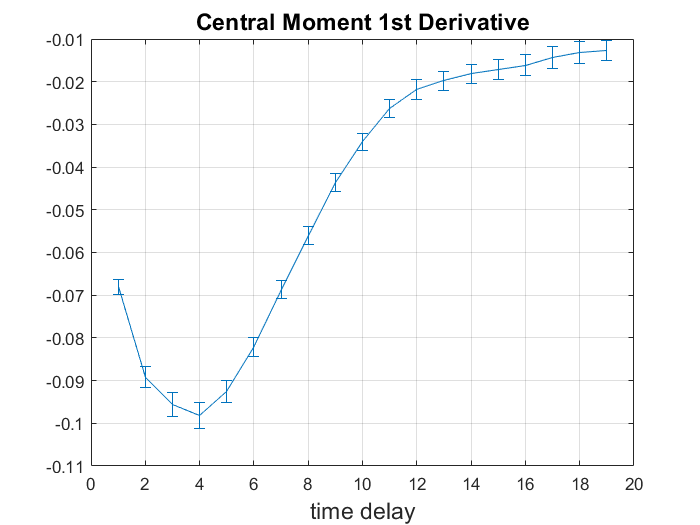

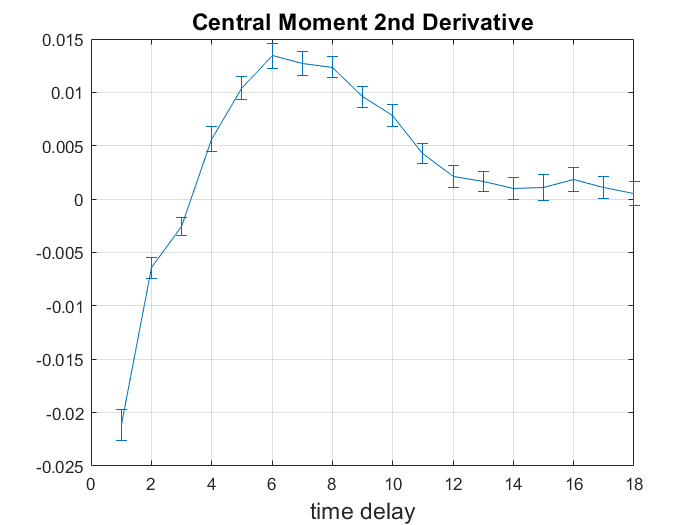

traces = cell(1);
min_len = 100;
idx = 1;
offset = 0;
min_val = 50;
for i = 1:length(trace_struct_final)
    fluo = trace_struct_final(i).fluo_interp;
    j = 1;
    start = 1;
    while j <= length(fluo)
        if fluo(j) <= min_val
            if j - start >= min_len
                traces{idx} = fluo(start:1:j-1);
                traces{idx} = traces{idx}((1+offset):(end - offset));
                idx = idx + 1;
            end
            start = j + 1;
        end
        j = j + 1;
    end
    if j - start >= min_len
        traces{idx} = fluo(start:1:j-1);
        traces{idx} = traces{idx}((1+offset):(end - offset));
        idx = idx + 1;
    end
end

gen_auto_cor(traces,0:2,true,20,0);

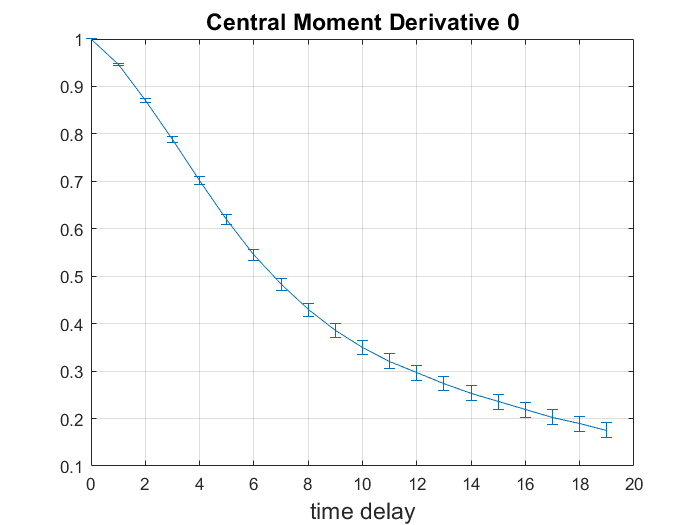

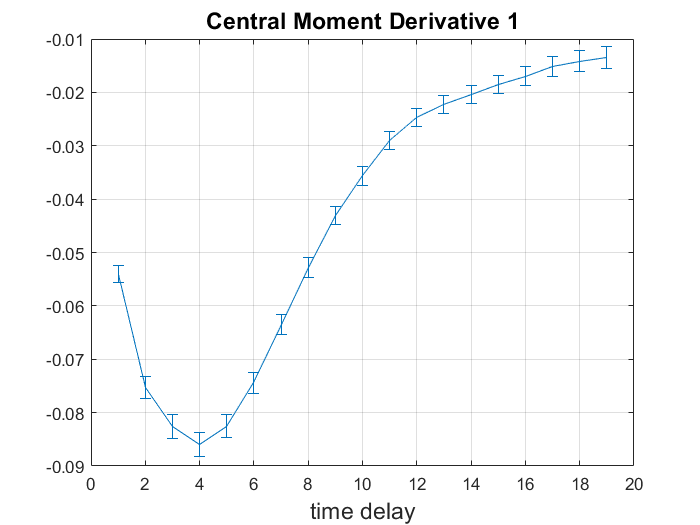

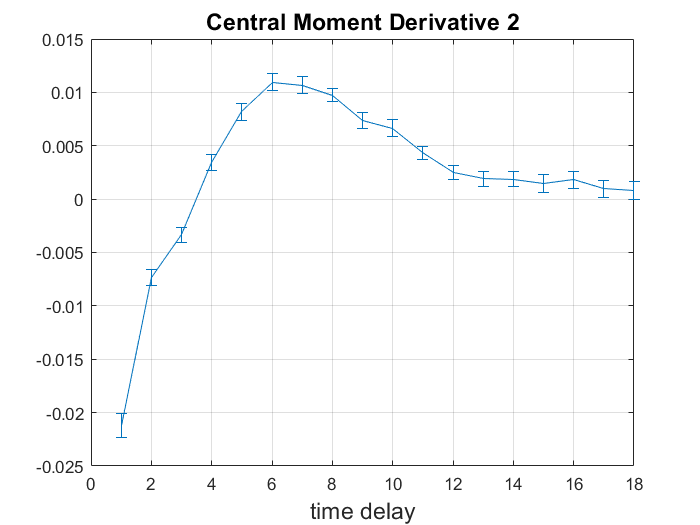

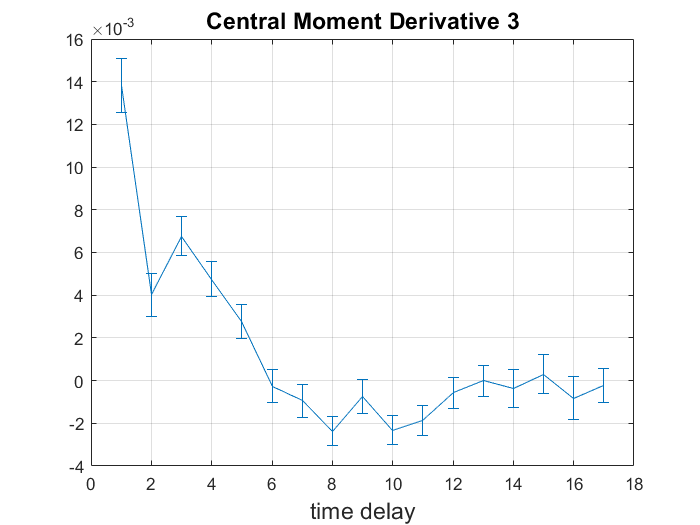

% normal autocorrelation
traces = {};
idx = 1;
min_len = 100;
min_nonzero = 50;
min_burst = 10;

for i = 1:length(trace_struct_final)
    trace = trace_struct_final(i).fluo_interp;
    zeroes = [0 find(trace == 0) length(trace) + 1];
    for j = 2:length(zeroes)
        if zeroes(j) - zeroes(j - 1) < 10
            trace(zeroes(j-1) + 1:zeroes(j) - 1) = 0;
        end
    end
    first_nonzero = find(trace > 0, 1, 'first');
    last_nonzero = find(trace > 0, 1, 'last');
    trace = trace(first_nonzero:last_nonzero);
    if length(trace) > 100 && length(find(trace > 0)) > min_nonzero
        traces{idx} = trace;
        idx = idx + 1;
    end
end
gen_auto_cor(traces,0:3,true,20,0);

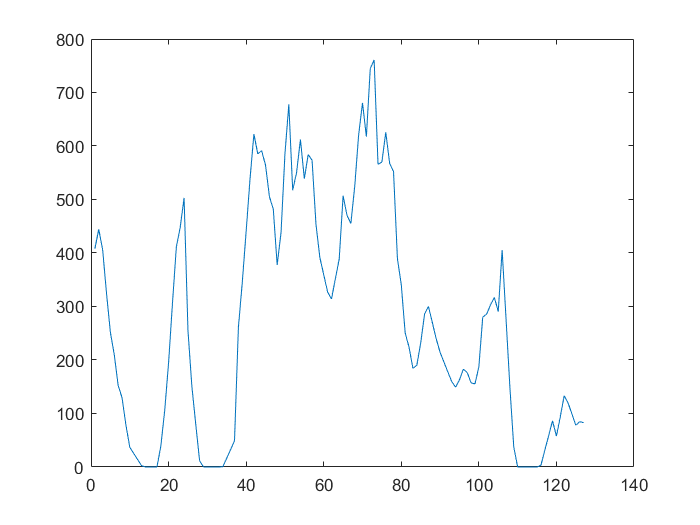

% looks at individual selected traces
i = 100;
figure();
plot(traces{i});

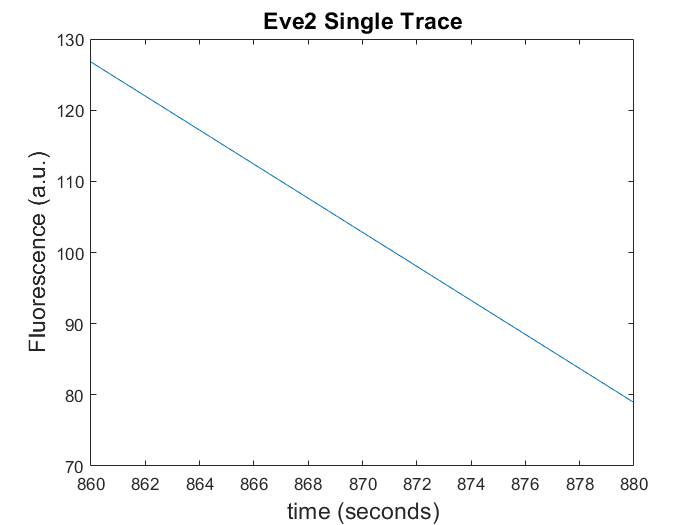

% looks at individual traces

i = 93;
figure();
plot(trace_struct_final(i).time_interp,trace_struct_final(i).fluo_interp);
xlabel('time (seconds)', 'FontSize', 14);
ylabel('Fluorescence (a.u.)', 'FontSize', 14);
title('Eve2 Single Trace', 'FontSize', 14);